# 全交换面积calc  1.1ver

%%
clear,clc
%参数
Lr = 4.1;%辐射管长度
Ws = 3.6;%钢板宽
Wfur = 4.6;%炉宽
epsilon_r = 0.5;%黑度
rho_r = 0.5;%反射率
epsilon_w = 0.85;
rho_w = 0.15;
epsilon_s = 0.75;
rho_s = 0.25;

%序号 直径 段长 h1 h2 辐射管间隔数组 功率数组
cellZoneInfo = {1,0.3,8.7,0.65,0.91,[2700 600 600 600 600 600 1200 600 1200],[115 150 115 150 115 150 115 150 115/2];
         2,0.3,7.2,0.65,0.91,[600 600 600 600 600 600 600 600 600 600 600 600],[115/2 150 115 150 115 150 115 150 115 150 115 150 95/2];
         3,0.28,7.2,0.66,0.92,[600 600 600 600 600 600 1200 600 1200 600],[95/2 120 95 120 95 120 95 120 95 120 95/2];
         4,0.28,7.2,0.66,0.92,[600 2400 600 600 1200 600 600 600],[95/2 120 95 120 95 120 95 120 95/2];
         5,0.28,7.2,0.66,0.92,[600 1200 600 1200 600 1200 600 1200],[95/2 120 95 120 95 120 95 120 95/2];
         6,0.28,7.2,0.66,0.92,[1200 1200 1200 1200 1200 1200],[95/2 120 95 120 95 120 95/2];
         7,0.28,6.6,0.66,0.92,[1200 2400 1800 1200],[95/2 120 95 120 95/2];
         8,0.208,7.2,0.696,0.956,[1800 1800 1800 1800],[95/2 80 55 80 55/2];
         9,0.208,7.2,0.696,0.956,[1800 1800 1800 1800],[55/2 80 55 80 55/2];
         10,0.208,7.2,0.696,0.956,[1800 1800 1800 1800],[55/2 80 55 80 55/2];
         11,0.208,9.3,0.696,0.956,[1800 1800 1800 1800 2100],[55/2 80 55 120 95];}

cellZoneInfo = 11×7 cell 数组
    {[ 1]}    {[0.3000]}    {[8.7000]}    {[0.6500]}    {[0.9100]}    {[         2700 600 600 600 600 600 1200 600 1200]}    {[                    115 150 115 150 115 150 115 150 57.5000]}
    {[ 2]}    {[0.3000]}    {[7.2000]}    {[0.6500]}    {[0.9100]}    {[600 600 600 600 600 600 600 600 600 600 600 600]}    {[57.5000 150 115 150 115 150 115 150 115 150 115 150 47.5000]}
    {[ 3]}    {[0.2800]}    {[7.2000]}    {[0.6600]}    {[0.9200]}    {[      600 600 600 600 600 600 1200 600 1200 600]}    {[            47.5000 120 95 120 95 120 95 120 95 120 47.5000]}
    {[ 4]}    {[0.2800]}    {[7.2000]}    {[0.6600]}    {[0.9200]}    {[              600 2400 600 600 1200 600 600 600]}    {[                   47.5000 120 95 120 95 120 95 120 47.5000]}
    {[ 5]}    {[0.2800]}    {[7.2000]}    {[0.6600]}    {[0.9200]}    {[            600 1200 600 1200 600 1200 600 1200]}    {[                   47.5000 120 95 120 95 120 95 120 47.5000]}
    {[ 6]}    {[0.2800]}   


SR = zeros(1,length(cellZoneInfo));
SW = zeros(1,length(cellZoneInfo));
WR = zeros(1,length(cellZoneInfo));


for i = 1:length(cellZoneInfo)

    %计算
    S = cellZoneInfo{i,6}./1000;%辐射管间隔数组
    d = cellZoneInfo{i,2};%辐射管直径
    L = cellZoneInfo{i,3};%段长
    h1 = cellZoneInfo{i,4};%见函数
    h2 = cellZoneInfo{i,5};
    kr = Lr/Wfur;%辐射管长度系数
    ks = Ws/Wfur;%钢板宽度系数

    xrp = zeros(1,length(S));
    for j = 1:length(S)
        if S(j) == 2.7 || S(j) == 2.1
            xrp(j) = (d/2)/S(j)*atan(S(j)/(d/2));
        else
            xrp(j) = S(j)/(pi*d)*(1+d/S(j)*acos(d/S(j))-(1-(d/S(j))^2)^(1/2));
        end
    end
    %加权辐射管对假想面角系数
    Xrp = 0;
    for j = 1:length(xrp)
        Xrp = Xrp+S(j)/L*xrp(j);
    end
    %角系数

    Xp1w2 = phi_p1_w2(Wfur,L,h1) + phi_p2_w1(Wfur,L,h1);
    Xp2s = phi_p2_s(Wfur,L,h2);
    Xp2w1 = phi_p2_w1(Wfur,L,h2);
    
    % 论文中修正的角系数
    % Xrs = Xrp * 1/kr * Xp2s * ks;
    Xrw = Xrp * 1/kr *Xp1w2 + Xrp * 1/kr *Xp2w1;
    Xrr = 1 - 2 * Xrp;
    % Xrr = 1 - Xrw - Xrs;
    Xrs = 1 - Xrw - Xrr;
    

    %不修正的角系数
    % Xrs = Xrp * Xp2s ;
    % Xrw = Xrp *Xp1w2 + Xrp *Xp2w1;
    % Xrr = 1 - 2 * Xrp;

    Fs = L*Ws;
    Fw = L*Wfur+L*h1*2+L*h2*2;
    Fr = pi*d*length(S)*Lr;

    Xss= 0;
    Xsr = Xrs * Fr/Fs;
    Xsw = 1 - Xsr - Xss;
    Xwr = Xrw * Fr/Fw;
    Xws = Xsw * Fs/Fw;
    Xww = 1 - Xwr - Xws;
    %直接交换面积
    rr = Fr * Xrr;
    rw = Fr * Xrw;
    rs = Fr * Xrs;
    wr = Fw * Xwr;
    ww = Fw * Xww;
    ws = Fw * Xws;
    sr = Fs * Xsr;
    sw = Fs * Xsw;
    ss = Fs * Xss;

    %全交换面积

    SR(i) = calculate_SR(Fr, Fw, Fs, epsilon_r, epsilon_s, rho_r, rho_w, rho_s, Xrr, Xws, Xsr, Xww, Xwr);
    SW(i) = calculate_SW(Fr, Fw, Fs, epsilon_w, epsilon_s, rho_r, rho_w, rho_s, Xrr, Xws, Xwr, Xsr, Xww);
    WR(i) = calculate_WR(Fr, Fw, Fs, epsilon_r, epsilon_w, rho_r, rho_w, rho_s, Xrr, Xwr, Xsr, Xsw, Xww);
    
end
% SR = SR + 100;
% SW = SW + 100;
% WR = WR + 100;

RS = SR

RS =     4.5115    7.0134    5.6168    4.5826    4.5835    3.5048    2.3996    1.7822    1.7822    1.7822    1.9301


WS = SW

WS =    17.3465   10.4000   11.9667   13.1323   13.1309   14.3494   14.0650   16.3139   16.3139   16.3139   21.5975


RW = WR

RW =     8.7697   12.8364   10.3866    8.5359    8.5374    6.5778    4.4526    3.3940    3.3940    3.3940    3.8616


SR

SR =     4.5115    7.0134    5.6168    4.5826    4.5835    3.5048    2.3996    1.7822    1.7822    1.7822    1.9301


SW

SW =    17.3465   10.4000   11.9667   13.1323   13.1309   14.3494   14.0650   16.3139   16.3139   16.3139   21.5975


WR

WR =     8.7697   12.8364   10.3866    8.5359    8.5374    6.5778    4.4526    3.3940    3.3940    3.3940    3.8616


# 三元法calc   ver1.1

%初(xia)始(gei)化温度
Tw_init = [700 720 740 760 780 800 820 840 860 870 870] + 273.15;
Ts_1_init = [150 250 420 555 666 777 820 835 850 870 870] + 273.15;
% Ts_1_init = [350 550 620 755 866 977 1020 1035 1050 1070 1070] + 273.15;
Tw_zone = zeros(1,length(cellZoneInfo));
Tr_zone = zeros(1,length(cellZoneInfo));
Ts_zone = zeros(1,length(cellZoneInfo));


Lfur = 82.2;%炉长,m
ths = 50/1000;%板厚,m
Time_heat = 80 * 60;%加热时间,s
Vs = Lfur / Time_heat;%物料速度
Thw = 0.3;%炉墙厚度
lambda_w = 0.138*250/300+0.15*50/300;%炉墙导热系数
hw = 10;%炉墙自然对流换热系数
Temp_out = 30+273.15;%环境温度,k
density_s = 7860;
sigma = 5.67*10^(-8);%斯忒藩-玻尔兹曼常数
N = 10;%层数
timeStep = 1000;%时间步长节点数
Ts_2 = 0;%初始化，进循环用
phi_r = zeros(1,length(cellZoneInfo));

Temp_inlet = zeros(N+1,length(cellZoneInfo));
Temp_inlet(:,1) = 30 + 273.15;
Temp_total = zeros(length(cellZoneInfo),timeStep*length(cellZoneInfo));

for i = 1:length(cellZoneInfo)

    phi_r(i) = sum(cellZoneInfo{i,7})*1000;%W
    Tw = Tw_init(i);
    Ts_1 = Ts_1_init(i);%段内物料表面初始温度
    L = cellZoneInfo{i,3};%段长
    Time_zone = L / Vs;%段内时间

    %能量平衡解Tr
    while(abs((Ts_2 - Ts_1)/Ts_1)>=0.001)
        Ts_1 = Ts_2;
        syms Tr;
        f1 = sigma*RW(i)*(Tr^4 - Tw^4) + sigma*RS(i)*(Tr^4 - Ts_1^4) == phi_r(i);
        Tr = solve(f1,Tr);
        Tr = vpa(Tr);
        Tr= Tr(imag(Tr) == 0 & real(Tr) > 0);

    %能量平衡解Tw   
        syms Tw;
        f2 = sigma*SW(i)*(Ts_1^4 - Tw^4) + sigma*RW(i)*(Tr^4 - Tw^4) == Fw*(Tw - Temp_out)/(1/hw+Thw/lambda_w);
        Tw = solve(f2,Tw);
        Tw = vpa(Tw);
        Tw= Tw(imag(Tw) == 0 & real(Tw) > 0);

    %求表面热流    
        qcon = -(sigma*RS(i)*(Ts_1^4 - Tr^4) + sigma*WS(i)*(Ts_1^4 - Tw^4))/Fs;%钢坯表面热流密度

    %差分求物料温度   
        T = Temp_inlet(:,i);
        delta_t = Time_zone / timeStep;%时间步长
        delta_x = ths/(2*N);%空间步长
        Temp_zone = zeros(length(cellZoneInfo),timeStep);
        for j = 1:timeStep
            T = TDMA(qcon,N,density_s,delta_t,delta_x,T);
            Temp_zone(:,j) = T;
        end
    
        Ts_2 = sum(Temp_zone(1,:))/timeStep;%热流反算物料表面温度
    
        % if abs((Ts_2 - Ts_1)/Ts_1)<=0.001
        %     break;
        % end
    end
    
    
    
    % sprintf('%.3e', phi_r(i)/sigma)
    % sprintf('%.3e', RW(i)*Tw^4)
    % sprintf('%.3e', RS(i)*Ts_2^4)

    Temp_inlet(:,i+1) = T
    Tw_zone(i) = Tw ;%K
    Tr_zone(i) = Tr ;%K
    Ts_zone(i) = Ts_2 ;%K
    Temp_total(:,1+(i-1)*timeStep:i*timeStep) = Temp_zone;%K

end

Temp_inlet =   303.1500  475.0731         0         0         0         0         0         0         0         0         0
  303.1500  473.2126         0         0         0         0         0         0         0         0         0
  303.1500  471.5528         0         0         0         0         0         0         0         0         0
  303.1500  470.0921         0         0         0         0         0         0         0         0         0
  303.1500  468.8289         0         0         0         0         0         0         0         0         0
  303.1500  467.7622         0         0         0         0         0         0         0         0         0
  303.1500  466.8908         0         0         0         0         0         0         0         0         0
  303.1500  466.2139         0         0         0         0         0         0         0         0         0
  303.1500  465.7308         0         0         0         0         0         0         0         

Temp_inlet =   303.1500  475.0731  658.2613         0         0         0         0         0         0         0         0
  303.1500  473.2126  655.1596         0         0         0         0         0         0         0         0
  303.1500  471.5528  652.3979         0         0         0         0         0         0         0         0
  303.1500  470.0921  649.9717         0         0         0         0         0         0         0         0
  303.1500  468.8289  647.8768         0         0         0         0         0         0         0         0
  303.1500  467.7622  646.1099         0         0         0         0         0         0         0         0
  303.1500  466.8908  644.6682         0         0         0         0         0         0         0         0
  303.1500  466.2139  643.5492         0         0         0         0         0         0         0         0
  303.1500  465.7308  642.7511         0         0         0         0         0         0         

Temp_inlet =   303.1500  475.0731  658.2613  765.3771         0         0         0         0         0         0         0
  303.1500  473.2126  655.1596  763.0224         0         0         0         0         0         0         0
  303.1500  471.5528  652.3979  760.9294         0         0         0         0         0         0         0
  303.1500  470.0921  649.9717  759.0932         0         0         0         0         0         0         0
  303.1500  468.8289  647.8768  757.5098         0         0         0         0         0         0         0
  303.1500  467.7622  646.1099  756.1757         0         0         0         0         0         0         0
  303.1500  466.8908  644.6682  755.0881         0         0         0         0         0         0         0
  303.1500  466.2139  643.5492  754.2445         0         0         0         0         0         0         0
  303.1500  465.7308  642.7511  753.6433         0         0         0         0         0         

Temp_inlet =   303.1500  475.0731  658.2613  765.3771  843.5215         0         0         0         0         0         0
  303.1500  473.2126  655.1596  763.0224  841.4734         0         0         0         0         0         0
  303.1500  471.5528  652.3979  760.9294  839.6466         0         0         0         0         0         0
  303.1500  470.0921  649.9717  759.0932  838.0394         0         0         0         0         0         0
  303.1500  468.8289  647.8768  757.5098  836.6499         0         0         0         0         0         0
  303.1500  467.7622  646.1099  756.1757  835.4766         0         0         0         0         0         0
  303.1500  466.8908  644.6682  755.0881  834.5183         0         0         0         0         0         0
  303.1500  466.2139  643.5492  754.2445  833.7740         0         0         0         0         0         0
  303.1500  465.7308  642.7511  753.6433  833.2430         0         0         0         0         

Temp_inlet =   303.1500  475.0731  658.2613  765.3771  843.5215  920.1490         0         0         0         0         0
  303.1500  473.2126  655.1596  763.0224  841.4734  917.9934         0         0         0         0         0
  303.1500  471.5528  652.3979  760.9294  839.6466  916.0640         0         0         0         0         0
  303.1500  470.0921  649.9717  759.0932  838.0394  914.3610         0         0         0         0         0
  303.1500  468.8289  647.8768  757.5098  836.6499  912.8846         0         0         0         0         0
  303.1500  467.7622  646.1099  756.1757  835.4766  911.6350         0         0         0         0         0
  303.1500  466.8908  644.6682  755.0881  834.5183  910.6124         0         0         0         0         0
  303.1500  466.2139  643.5492  754.2445  833.7740  909.8169         0         0         0         0         0
  303.1500  465.7308  642.7511  753.6433  833.2430  909.2486         0         0         0         

Temp_inlet =   303.1500  475.0731  658.2613  765.3771  843.5215  920.1490  974.3048         0         0         0         0
  303.1500  473.2126  655.1596  763.0224  841.4734  917.9934  972.7166         0         0         0         0
  303.1500  471.5528  652.3979  760.9294  839.6466  916.0640  971.2951         0         0         0         0
  303.1500  470.0921  649.9717  759.0932  838.0394  914.3610  970.0405         0         0         0         0
  303.1500  468.8289  647.8768  757.5098  836.6499  912.8846  968.9529         0         0         0         0
  303.1500  467.7622  646.1099  756.1757  835.4766  911.6350  968.0325         0         0         0         0
  303.1500  466.8908  644.6682  755.0881  834.5183  910.6124  967.2793         0         0         0         0
  303.1500  466.2139  643.5492  754.2445  833.7740  909.8169  966.6934         0         0         0         0
  303.1500  465.7308  642.7511  753.6433  833.2430  909.2486  966.2749         0         0         

Temp_inlet = 1.0e+03 *

    0.3031    0.4751    0.6583    0.7654    0.8435    0.9201    0.9743    1.0060         0         0         0
    0.3031    0.4732    0.6552    0.7630    0.8415    0.9180    0.9727    1.0050         0         0         0
    0.3031    0.4716    0.6524    0.7609    0.8396    0.9161    0.9713    1.0041         0         0         0
    0.3031    0.4701    0.6500    0.7591    0.8380    0.9144    0.9700    1.0033         0         0         0
    0.3031    0.4688    0.6479    0.7575    0.8366    0.9129    0.9690    1.0026         0         0         0
    0.3031    0.4678    0.6461    0.7562    0.8355    0.9116    0.9680    1.0020         0         0         0
    0.3031    0.4669    0.6447    0.7551    0.8345    0.9106    0.9673    1.0015         0         0         0
    0.3031    0.4662    0.6435    0.7542    0.8338    0.9098    0.9667    1.0011         0         0         0
    0.3031    0.4657    0.6428    0.7536    0.8332    0.9092    0.9663    1.0008        

Temp_inlet = 1.0e+03 *

    0.3031    0.4751    0.6583    0.7654    0.8435    0.9201    0.9743    1.0060    1.0291         0         0
    0.3031    0.4732    0.6552    0.7630    0.8415    0.9180    0.9727    1.0050    1.0284         0         0
    0.3031    0.4716    0.6524    0.7609    0.8396    0.9161    0.9713    1.0041    1.0278         0         0
    0.3031    0.4701    0.6500    0.7591    0.8380    0.9144    0.9700    1.0033    1.0272         0         0
    0.3031    0.4688    0.6479    0.7575    0.8366    0.9129    0.9690    1.0026    1.0268         0         0
    0.3031    0.4678    0.6461    0.7562    0.8355    0.9116    0.9680    1.0020    1.0264         0         0
    0.3031    0.4669    0.6447    0.7551    0.8345    0.9106    0.9673    1.0015    1.0261         0         0
    0.3031    0.4662    0.6435    0.7542    0.8338    0.9098    0.9667    1.0011    1.0258         0         0
    0.3031    0.4657    0.6428    0.7536    0.8332    0.9092    0.9663    1.0008    1.02

Temp_inlet = 1.0e+03 *

    0.3031    0.4751    0.6583    0.7654    0.8435    0.9201    0.9743    1.0060    1.0291    1.0513         0
    0.3031    0.4732    0.6552    0.7630    0.8415    0.9180    0.9727    1.0050    1.0284    1.0507         0
    0.3031    0.4716    0.6524    0.7609    0.8396    0.9161    0.9713    1.0041    1.0278    1.0501         0
    0.3031    0.4701    0.6500    0.7591    0.8380    0.9144    0.9700    1.0033    1.0272    1.0497         0
    0.3031    0.4688    0.6479    0.7575    0.8366    0.9129    0.9690    1.0026    1.0268    1.0492         0
    0.3031    0.4678    0.6461    0.7562    0.8355    0.9116    0.9680    1.0020    1.0264    1.0489         0
    0.3031    0.4669    0.6447    0.7551    0.8345    0.9106    0.9673    1.0015    1.0261    1.0486         0
    0.3031    0.4662    0.6435    0.7542    0.8338    0.9098    0.9667    1.0011    1.0258    1.0483         0
    0.3031    0.4657    0.6428    0.7536    0.8332    0.9092    0.9663    1.0008    1.02

Temp_inlet = 1.0e+03 *

    0.3031    0.4751    0.6583    0.7654    0.8435    0.9201    0.9743    1.0060    1.0291    1.0513    1.0737
    0.3031    0.4732    0.6552    0.7630    0.8415    0.9180    0.9727    1.0050    1.0284    1.0507    1.0731
    0.3031    0.4716    0.6524    0.7609    0.8396    0.9161    0.9713    1.0041    1.0278    1.0501    1.0725
    0.3031    0.4701    0.6500    0.7591    0.8380    0.9144    0.9700    1.0033    1.0272    1.0497    1.0720
    0.3031    0.4688    0.6479    0.7575    0.8366    0.9129    0.9690    1.0026    1.0268    1.0492    1.0716
    0.3031    0.4678    0.6461    0.7562    0.8355    0.9116    0.9680    1.0020    1.0264    1.0489    1.0712
    0.3031    0.4669    0.6447    0.7551    0.8345    0.9106    0.9673    1.0015    1.0261    1.0486    1.0710
    0.3031    0.4662    0.6435    0.7542    0.8338    0.9098    0.9667    1.0011    1.0258    1.0483    1.0707
    0.3031    0.4657    0.6428    0.7536    0.8332    0.9092    0.9663    1.0008    1.02

Temp_inlet = 1.0e+03 *

    0.3031    0.4751    0.6583    0.7654    0.8435    0.9201    0.9743    1.0060    1.0291    1.0513    1.0737    1.1155
    0.3031    0.4732    0.6552    0.7630    0.8415    0.9180    0.9727    1.0050    1.0284    1.0507    1.0731    1.1146
    0.3031    0.4716    0.6524    0.7609    0.8396    0.9161    0.9713    1.0041    1.0278    1.0501    1.0725    1.1138
    0.3031    0.4701    0.6500    0.7591    0.8380    0.9144    0.9700    1.0033    1.0272    1.0497    1.0720    1.1131
    0.3031    0.4688    0.6479    0.7575    0.8366    0.9129    0.9690    1.0026    1.0268    1.0492    1.0716    1.1126
    0.3031    0.4678    0.6461    0.7562    0.8355    0.9116    0.9680    1.0020    1.0264    1.0489    1.0712    1.1121
    0.3031    0.4669    0.6447    0.7551    0.8345    0.9106    0.9673    1.0015    1.0261    1.0486    1.0710    1.1116
    0.3031    0.4662    0.6435    0.7542    0.8338    0.9098    0.9667    1.0011    1.0258    1.0483    1.0707    1.1113
    0.30

Tw_zone - 273.15%各段温度

ans =   623.9721  790.3027  730.5604  727.8058  770.8919  777.8973  783.1155  780.8670  799.0423  819.3114  853.5772


Tr_zone - 273.15

ans = 1.0e+03 *

    0.9041    0.9535    0.9054    0.9089    0.9357    0.9445    0.9514    0.9406    0.9441    0.9581    1.0084


Ts_zone - 273.15

ans =   119.6306  296.5362  437.9749  530.9332  608.8994  673.1631  716.1118  743.8192  766.9705  789.3617  821.8876


Temp_zone(1,timeStep) - 273.15 %物料出炉温度

ans = 842.3082

Temp_total = Temp_total -273.15%钢温温度场

Temp_total =    33.4044   32.5970   33.9507   33.9646   34.6441   34.8880   35.3277   35.6194   35.9622   36.2499   36.5457   36.8173   37.0853   37.3402   37.5890   37.8292   38.0635   38.2914   38.5142   38.7321   38.9457   39.1552   39.3612   39.5639   39.7637   39.9607   40.1554   40.3478   40.5382   40.7268   40.9137   41.0991   41.2831   41.4659   41.6475   41.8281   42.0078   42.1866   42.3646   42.5419   42.7185   42.8946   43.0701   43.2452   43.4198   43.5939   43.7678   43.9412   44.1144   44.2873
   31.3026   31.5745   32.2581   32.6045   33.0656   33.4072   33.7723   34.0893   34.4042   34.6956   34.9790   35.2485   35.5096   35.7611   36.0054   36.2423   36.4732   36.6983   36.9184   37.1338   37.3451   37.5527   37.7568   37.9578   38.1559   38.3516   38.5449   38.7361   38.9253   39.1129   39.2988   39.4833   39.6665   39.8485   40.0294   40.2093   40.3883   40.5665   40.7439   40.9207   41.0969   41.2725   41.4475   41.6221   41.7963   41.9701   42.1436   42.3167   42.






% 获取所有处理区间的长度，并将其转换为 x 坐标区间长度
process_vector = [cellZoneInfo{:,3}] * 1000;

% 初始化 x 坐标和 y 坐标
x_total = [];
y1_total = [];
y11_total = [];

% 累积和计算 x 坐标
x_start = 0;
for i = 1:length(cellZoneInfo)
    % 计算当前区间的 x 坐标
    x_end = x_start + process_vector(i);
    x = linspace(x_start, x_end, timeStep);
    x_total = [x_total, x];
    
    % 创建当前区间的矩阵 
    matrix = Temp_total(:, 1 + (i-1) * timeStep : i * timeStep);
    
    % 提取第一行和最后一行
    y1 = matrix(1, :);
    y11 = matrix(11, :);
    
    % 累积 y 坐标
    y1_total = [y1_total, y1];
    y11_total = [y11_total, y11];
    
    % 更新 x 起点
    x_start = x_end;
end

# 绘图      1.0ver

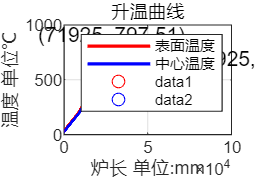

%物料升温曲线
% 绘制折线图
figure;
plot(x_total, y1_total, 'r-', 'LineWidth', 1.5); % 第一行用红色绘制
hold on;
plot(x_total, y11_total, 'b-', 'LineWidth', 1.5); % 最后一行用蓝色绘制

% 添加图例和标签
legend('表面温度', '中心温度');
xlabel('炉长 单位:mm');
ylabel('温度 单位℃');
title('升温曲线');

% 显示网格
grid on;

% 查找 x = 71925 对应的 y 值
x_target = 71925;
[~, idx] = min(abs(x_total - x_target)); % 找到最接近 x_target 的索引
y1_target = y1_total(idx);
y11_target = y11_total(idx);

% 在图中标注 x = 71925 时对应的 y 值
plot(x_target, y1_target, 'ro'); % 在表面温度曲线上的标注
text(x_target, y1_target, sprintf('(%d, %.2f)', x_target, y1_target), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');

plot(x_target, y11_target, 'bo'); % 在中心温度曲线上的标注
text(x_target, y11_target, sprintf('(%d, %.2f)', x_target, y11_target), 'VerticalAlignment', 'top', 'HorizontalAlignment', 'left');

hold off;

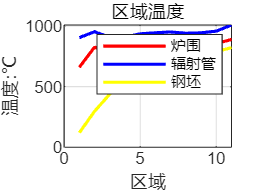



%三元各区域升温曲线
x = linspace(1,11,11);
yTw = Tw_zone - 237.15;
yTr = Tr_zone - 273.15;
yTs = Ts_zone - 273.15;

% 绘制折线图
figure;
plot(x, yTw, 'r-', 'LineWidth', 1.5);
hold on;
plot(x, yTr, 'b-', 'LineWidth', 1.5); 
hold on;
plot(x, yTs, 'y-', 'LineWidth', 1.5); 


% 添加图例和标签
legend('炉围', '辐射管', '钢坯');
xlabel('区域');
ylabel('温度:℃');
title('区域温度');

% 显示网格
grid on;
hold off;

**函数**

%计算空间角系数
%x为炉宽，m;h为炉高，m;y为炉段长度，m;h1为辐射管上端距炉墙高度，m;h2为辐射管下端距假象面p高度，m
function phi = phi_p1_w2(x, y, h1)
    X = x / h1;
    Y = y / h1;
    
    term1 = sqrt((1 + X^2) * (1 + Y^2)) / (1 + X^2 + Y^2);
    term2 = X * sqrt(1 + Y^2) * atan(X / sqrt(1 + Y^2));
    term3 = Y * sqrt(1 + X^2) * atan(Y / sqrt(1 + X^2));
    term4 = X * atan(X) + Y * atan(Y);
    
    phi = (2 / (pi * X * Y)) * (log(term1) + term2 + term3 - term4);
end

function phi = phi_p2_s(x, y, h2)
    X = x / h2;
    Y = y / h2;
    
    term1 = sqrt((1 + X^2) * (1 + Y^2)) / (1 + X^2 + Y^2);
    term2 = X * sqrt(1 + Y^2) * atan(X / sqrt(1 + Y^2));
    term3 = Y * sqrt(1 + X^2) * atan(Y / sqrt(1 + X^2));
    term4 = X * atan(X) + Y * atan(Y);
    
    phi = (2 / (pi * X * Y)) * (log(term1) + term2 + term3 - term4);
end

function phi = phi_p2_w1(x, y, h2)
    H = h2 / y;
    W = x / y;
    
    term1 = W * atan(1 / W) + H * atan(1 / H);
    term2 = sqrt(H^2 + W^2) * atan(1 / sqrt(H^2 + W^2));
    term3 = (1 + W^2) * (1 + H^2) / (1 + W^2 + H^2) * (W^2 * (1 + W^2 + H^2) / ((1 + W^2) * (W^2 + H^2)))^(W^2);
    term4 = (H^2 * (1 + H^2 + W^2) / ((1 + H^2) * (H^2 + W^2)))^(H^2);
    phi = (2 / (pi * W)) * (term1 - term2 + 1/4*log(term3 * term4));
end

function phi = phi_p2_w11(x, y, h2)
    % 定义H和W
    H = h2 / y;
    W = x / y;
    
    % 计算第一部分
    part1 = W * atan(1 / W) + H * atan(1 / H);
    
    % 计算第二部分
    part2 = sqrt(H^2 + W^2) * atan(1 / sqrt(H^2 + W^2));
    
    % 计算第三部分中的内部分数
    term1_numerator = (1 + W^2) * (1 + H^2);
    term1_denominator = 1 + W^2 + H^2;
    term1 = term1_numerator / term1_denominator;
    
    term2_numerator = W^2 * (1 + W^2 + H^2);
    term2_denominator = (1 + W^2) * (W^2 + H^2);
    term2 = term2_numerator / term2_denominator;
    term2 = term2^(W^2);
    
    term3_numerator = H^2 * (1 + H^2 + W^2);
    term3_denominator = (1 + H^2) * (H^2 + W^2);
    term3 = term3_numerator / term3_denominator;
    term3 = term3^(H^2);
    
    % 计算第三部分
    part3 = (1/4) * log(term1 * term2 * term3);
    
    % 计算最终结果
    phi = (2 / (pi * W)) * (part1 - part2 + part3);
    
end

%全交换面积计算

function SR = calculate_SR(Fr, Fw, Fs, epsilon_r, epsilon_s, rho_r, rho_w, rho_s, Xrr, Xws, Xsr, Xww, Xwr)
    % 计算 SR
    numerator = -Fr * epsilon_r * Fs * epsilon_s * (-Fw * rho_w * Xwr * Xws + Fs * Xsr * (-1 + rho_w * Xww));
    denominator = Fr * (-1 + rho_r * Xrr) * (Fw * rho_s * rho_w * Xws^2 + Fs * (-1 + rho_w * Xww)) ...
                  + Fs * rho_r * (-Fw * rho_w * Xwr * (Xwr + 2 * rho_s * Xsr * Xws) + Fs * rho_s * Xsr^2 * (-1 + rho_w * Xww));
    SR = numerator / denominator;
end

function SW = calculate_SW(Fr, Fw, Fs, epsilon_w, epsilon_s, rho_r, rho_w, rho_s, Xrr, Xws, Xwr, Xsr, Xww)
    % 计算 SW
    numerator = Fw * epsilon_w * Fs * epsilon_s * (Fs * rho_r * Xsr * Xwr + Fr * (1 - rho_r * Xrr) * Xws);
    denominator = Fr * (-1 + rho_r * Xrr) * (Fw * rho_s * rho_w * Xws^2 + Fs * (-1 + rho_w * Xww)) ...
                  + Fs * rho_r * (-Fw * rho_w * Xwr * (Xwr + 2 * rho_s * Xsr * Xws) + Fs * rho_s * Xsr^2 * (-1 + rho_w * Xww));
    SW = numerator / denominator;
end

function WR = calculate_WR(Fr, Fw, Fs, epsilon_r, epsilon_w, rho_r, rho_w, rho_s, Xrr, Xwr, Xsr, Xsw, Xww)
    % 计算 WR
    numerator = Fr * epsilon_r * Fw * epsilon_w * (Fs * rho_s * Xsr * Xsw + Fw * Xwr);
    denominator = -Fr * (-1 + rho_r * Xrr) * (Fs * rho_s * rho_w * Xsw^2 + Fw * (-1 + rho_w * Xww)) ...
                  + Fw * rho_r * (Fw * rho_w * Xwr^2 + Fs * rho_s * Xsr * (Xsr + 2 * rho_w * Xsw * Xwr - rho_w * Xsr * Xww));
    WR = -numerator / denominator;
end

%TDMA求解全隐式差分
%热流 离散层数 密度 时间步长 空间步长 上一时刻温度场
function T = TDMA(Qcon,N,density,delta_t,delta_x,T)
    %初始化
    Cp_point = zeros(1,N+1);
    Lambda_point = zeros(1,N+1);

    for i = 1 : N+1
        [Cp_point(i) , Lambda_point(i)] = calPhysicalParameters(1 , T(i));
    end
    Cp_layer = computeAdjacentAverages(Cp_point);
    Lambda_Layer = computeAdjacentHarmonicAverages(Lambda_point);
    Fo = Lambda_Layer./(density.*Cp_layer)*delta_t/(delta_x^2);
    T(1) = T(1) + 2*Fo(1)*(T(2) - T(1) + Qcon*delta_x/Lambda_Layer(1));
    T(N+1) = T(N+1) + 2*Fo(N)*(T(N) - T(N+1));
    a = -Fo(2:N-1);
    b = 1 + computeAdjacentSums(Fo);
    c = -Fo(2:N-1);
    d = T(2:N);
    d(1) = d(1) + Fo(1) * T(1);
    d(N-1) = d(N-1) + Fo(N) * T(N+1);
    
    x = tridiagonal_vector(a,b,c,d);%三对角矩阵算法
    % 检查向量长度以确保可以替换
    if length(T) < 2 || length(x) ~= length(T) - 2
        error('向量 T 和 x 的长度不匹配，无法进行替换');
    end
    % 替换 T 的第 2 到第 N 个元素为 x 的第 1 到第 N-1 个元素
    T(2:end-1) = x;
end


%计算相邻两元素的算术平均值
function avgArray = computeAdjacentAverages(inputArray)
    % 检查输入是否为非空的一维数组
    if isempty(inputArray) || ~isvector(inputArray)
        error('输入必须是一个非空的一维数组');
    end

    % 获取输入数组的长度
    n = length(inputArray);

    % 如果输入数组的长度小于2，无法计算相邻元素的平均值
    if n < 2
        error('输入数组的长度必须至少为2');
    end

    % 预分配输出数组
    avgArray = zeros(1, n-1);

    % 计算相邻元素的算术平均值
    for i = 1:n-1
        avgArray(i) = (inputArray(i) + inputArray(i+1)) / 2;
    end
end


%计算相邻两元素的调和平均值
function harmonicAvgArray = computeAdjacentHarmonicAverages(inputArray)
    % 检查输入是否为非空的一维数组
    if isempty(inputArray) || ~isvector(inputArray)
        error('输入必须是一个非空的一维数组');
    end

    % 获取输入数组的长度
    n = length(inputArray);

    % 如果输入数组的长度小于2，无法计算相邻元素的调和平均值
    if n < 2
        error('输入数组的长度必须至少为2');
    end

    % 预分配输出数组
    harmonicAvgArray = zeros(1, n-1);

    % 计算相邻元素的调和平均值
    for i = 1:n-1
        harmonicAvgArray(i) = 2 / (1/inputArray(i) + 1/inputArray(i+1));
    end
end

%计算两相邻元素的加和
function sumArray = computeAdjacentSums(inputArray)
    % 检查输入是否为非空的一维数组
    if isempty(inputArray) || ~isvector(inputArray)
        error('输入必须是一个非空的一维数组');
    end

    % 获取输入数组的长度
    n = length(inputArray);

    % 如果输入数组的长度小于2，无法计算相邻元素的和
    if n < 2
        error('输入数组的长度必须至少为2');
    end

    % 预分配输出数组
    sumArray = zeros(1, n-1);

    % 计算相邻元素的和
    for i = 1:n-1
        sumArray(i) = inputArray(i) + inputArray(i+1);
    end
end


